## Source estimation using the Minimum Norm inverse projection approach

 first, load the source model which is located in the libas/4data folder

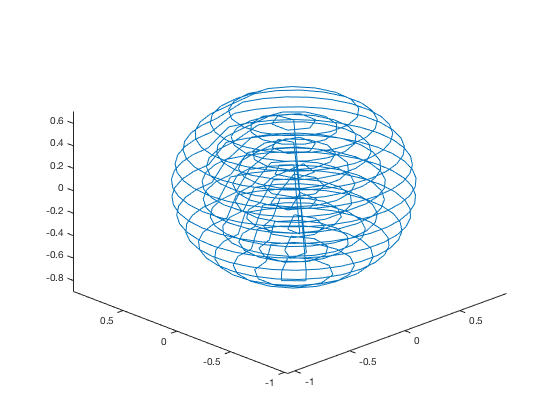

clear

load dipoles_symmetric.dat

plot3(dipoles_symmetric(:,1), dipoles_symmetric(:,2), dipoles_symmetric(:,3))

this should look like a 1950's lampshade, 4 shells on a unit sphere...

next, load the electrode locations in Cartesian coordinates

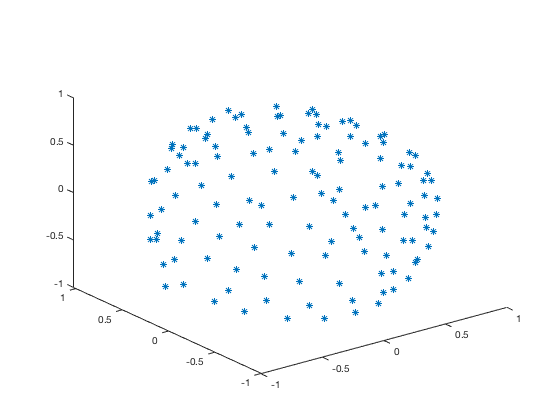

load elek129HCLnorm.dat
% this for example loads the sensor positions for the 129 EGI HCL electrode array. 
% these are just cartesion 3-D coordinates (X, Y, Z)
% Many elec files are located in the 4data folder 
% again, check to make sure that the sensor positions fit on a unit sphere
plot3(elek129HCLnorm(:,1),elek129HCLnorm(:,2),elek129HCLnorm(:,3), '*')

% 

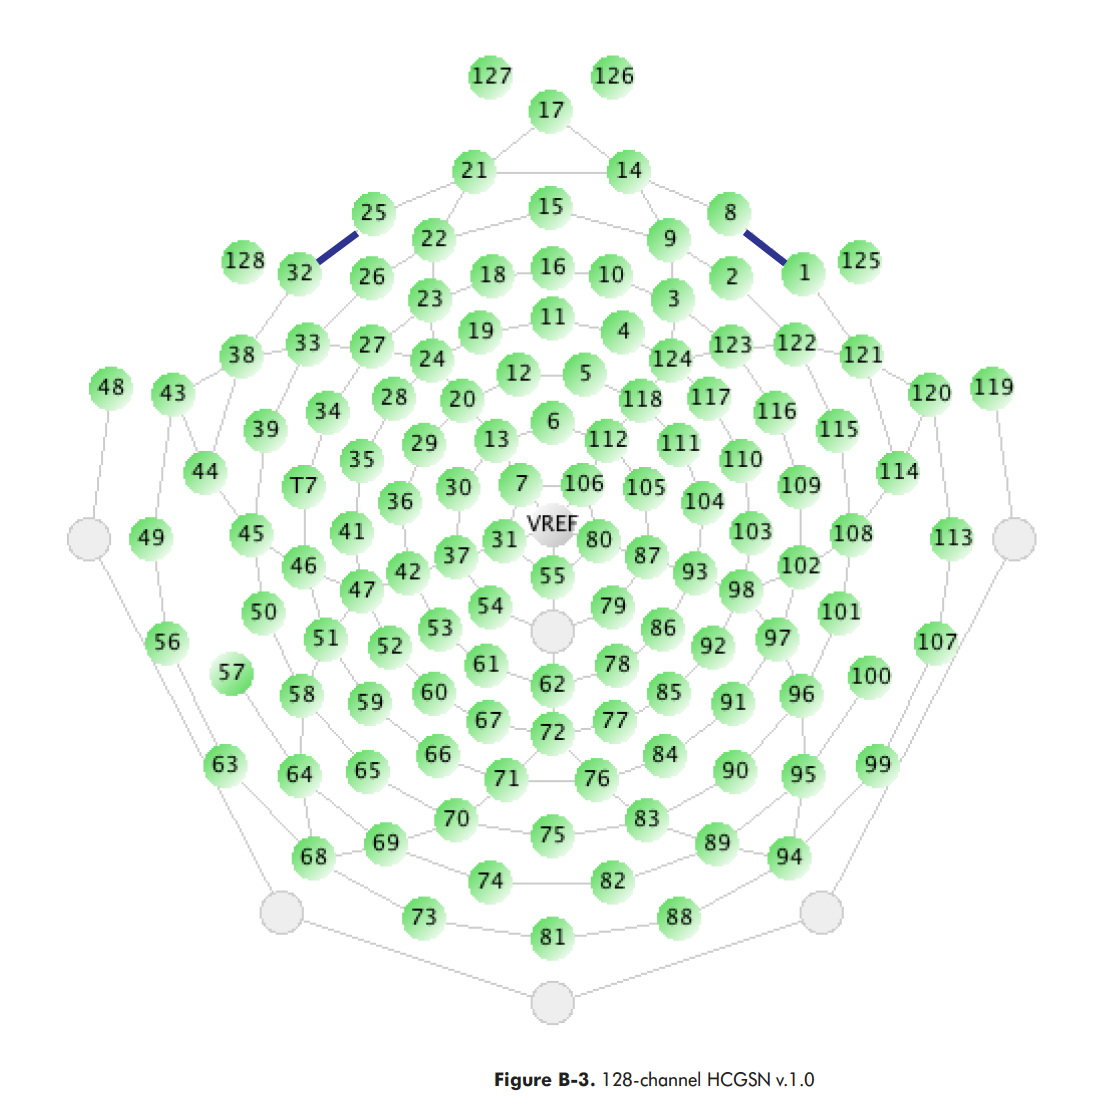Thi is the electrode layout, elect 75 is approximately Oz

if not on a unit sphere, then put on a unit sphere by a simple multiplication using this code

elek129HCLnorm = elek129HCLnorm.*10

replot to make sure that the positions lie on a unit sphere

plot3(elek129HCLnorm(:,1),elek129HCLnorm(:,2),elek129HCLnorm(:,3), '*')

In the example, the electrodes are already on a sphere

% now ready to do source analysis
% first calculate leadfield (this will be the same for all people with this electrode net
% so you can save and use for later studies with the SAME sensor net
[lfd_mat, orientations]=compute_lfdmat(dipoles_symmetric', elek129HCLnorm', 'eeg', 'xyz');


1 of 655 done ... 
................................................
50 of 655 done ... 
.................................................
100 of 655 done ... 
.................................................
150 of 655 done ... 
.................................................
200 of 655 done ... 
.................................................
250 of 655 done ... 
.................................................
300 of 655 done ... 
.................................................
350 of 655 done ... 
.................................................
400 of 655 done ... 
.................................................
450 of 655 done ... 
.................................................
500 of 655 done ... 
.................................................
550 of 655 done ... 
.................................................
600 of 655 done ... 
.................................................
650 of 655 done ... 
.....0.800004   350
0.600005   547
0.400002   634
0.200001 

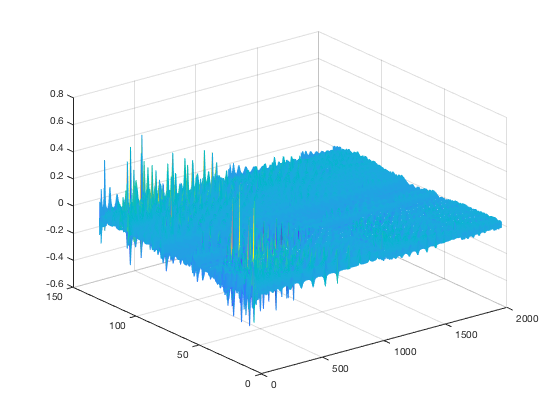

% note that the dipoles and the eleks need to have dimensions of 3 by something (3 x eleks and 3 x dipoles)
% this is why the dipoles were transposed in the example above
% for those interested, look at the compute_lfdmat program and the function it calls
mesh(lfd_mat)

Now, read the 3-D data files (channels by time by trials) 

load('bop_106.fl40h1.E1.app1.mat');
load taxis.mat

and now, average the trials together, by averaging across the third dimension of this object. 

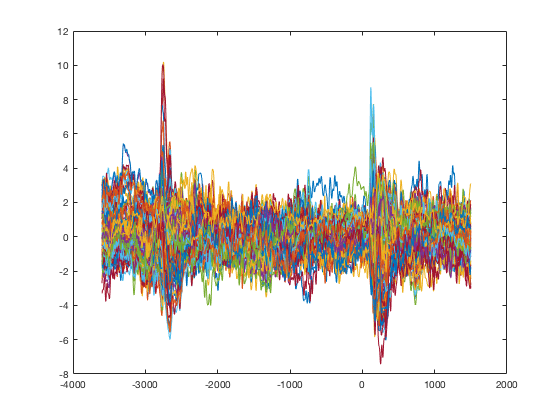

ERPmat = mean(outmat, 3); 
plot(taxis, ERPmat')

save ERPmat.mat ERPmat -mat % saves the average to disk

Now we are ready to run the actual MNE (minimum norm estimation)

% first set input parameters, we already have a few
regpar = 0.01; %regularization parameter
directory = pwd % the folder we read/write from/to

directory = '/Users/andreaskeil/Desktop/tmp_zurich/example_data'

filename = 'ERPmat.mat'; 
from = 1; 
to = 2551; % just the whole length of the signal in sample points, sometimes you may want to estimate only a subset of sample points
output = 'abs'; % use abs for absolute current density, and 'rad' for only the radial component
baseline = 200:300; % Base;line segment to be subtracted, in sample points

[diploc, lfdmat, data, G, invsol] = invmap_reduce_mat(lfd_mat, dipoles_symmetric, regpar, directory, filename , directory, [], elek129HCLnorm', from, to, output, baseline);

/Users/andreaskeil/Desktop/tmp_zurich/example_data/ERPmat.mat
Reading data, only the first trial
 Determine valid electrodes to be included in the following procedure
Computing pseudoinverse (G)


ans =         1965         129


0.800004   350
0.600005   547
0.400002   634
0.200001   655
Computing and writing  inverse solutions (invsol)


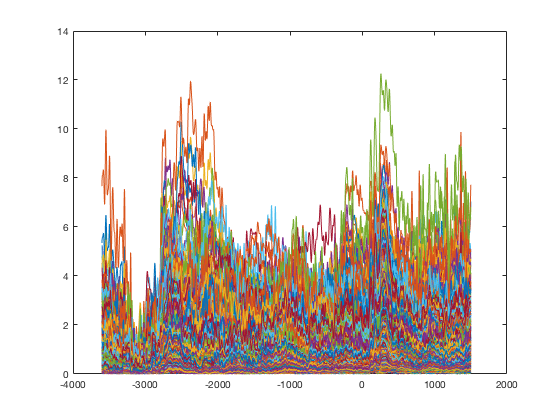

plot(taxis, invsol')